# Acoustic Index Analysis of the EigenScape Data Set

## Background

Acoustic Indices have been developed almost exclusively for the purpose of analysing the biodiversity of environments by using acoustic data, but previous research has suggested that these indices can be used to draw more general conclusions about soundscapes such as the 'naturalness' of a soundscape \cite(Devos2016, ﻿Green2019). The purpose of these indicies is often to identify the features of natural sounds while being robust to or considerate of human made or mechanical sound sources such as cars and planes. An example of such an index is the Normalised Difference Soundscape Index (NDSI) which was first developed by Kasten *et al.* \cite(﻿Kasten2012). ﻿The NDSI is a the proportional relationship between the sum of the power of two separate frequency ranges, the range of 1kHz to 2kHz being used to identify 'more mechanical sounds' and the 2kHz to 11kHz region being used to identify 'more natural sounds'. The intuition behind the choice of spectral regions being that mechanical sounds tend to be slower or lower in frequency than natural sounds. 

A major tennat of the soundscape research paradigm is that of human affective evalution of and responses to soundscapes, the aim of these studies is often to identify how human evaluation of soundscapes might be improved by changing the soundscape; often by some form of architectural or acoustic augmentation, such as the installation of water features and noise attenuating barriers **CITE**. An example of such as study is .... who ... and shows that .... **CITE**. Work by Stevens *et al.* has further explored how human affective responses relate to soundscape class .... **CITE**. It is commonly reported in many studies in soundscape literature that humans often have a more positive affective response to more natural soundscapes, and a more negative affetive response to industrial and mechanical soundscapes. When attempting to evaluate a soundscape with metrics in proxy of direct human affective ratings, if it holds true that acoustic indicies can represent feautres of soundscapes that relate to how they are percieved such as more natural meaning more pleasant, it should be the case that humans affective evaluation of soundscapes correlates positively with the infered naturalness of acoustic index scores for these soundscapes. 

The EigenScape data set is a set of eight ambisonic recordings of eight different classes of soundscape, a total of 64 ten minute soundscape recordings that was recorded by Green in May of 2017 \cite(﻿Green2017). The dataset includes a broad range of soundscape types including:

- Beach

- Busy Street

- Park

- Pedestrian Zone

- Shopping Centre

- Train Station

- Woodland

The locations of each recording in the data-set are conveniently presented in a google map that is available through the data set repository, a copy of the map is present in figure 1.

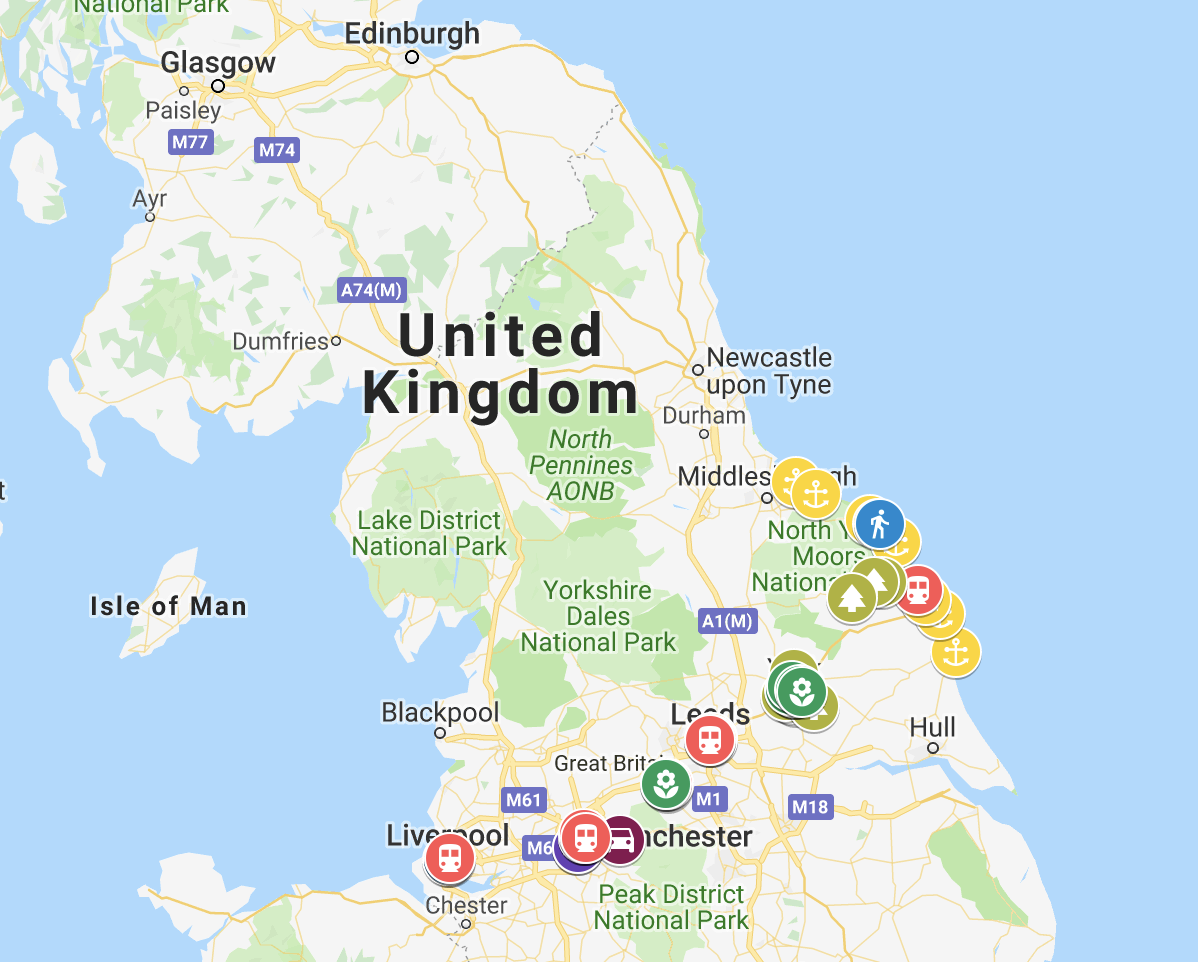

The purpose of this report is to evaluate the acoustic index rating of the EigenScape dataset, split into contiguous frames of 40 seconds. The soundscape segments that are identified as most and least natural will be used in an evaluatory soundscape experiment, where participants will classify and affectively rate their experience of the most and least 'natural' soundscape clips. The aim of this report is to identify how acoustic indices might be used to evaluate general perceptual features of soundscape recordings i.e. naturalness.

### Load Data

The acoustic indices were post-processed using tools in Python. Lets load the data.

% filename = 'indices_eigenscape_5_8_19.csv';
filename = 'indices_eigenscape_7_8_19.csv';
Indices = importIndices(filename);
head(Indices)

ans = 8×20 table
        filename        Acoustic_Complexity_Index__main_value    Acoustic_Complexity_Index__min    Acoustic_Complexity_Index__max    Acoustic_Complexity_Index__mean    Acoustic_Complexity_Index__median    Acoustic_Complexity_Index__std    Acoustic_Complexity_Index__var    Acoustic_Diversity_Index__main_value    Acoustic_Evenness_Index__main_value    Bio_acoustic_Index__main_value    Normalized_Difference_Sound_Index__main_value    RMS_energy__min    RMS_energy__max    RMS_energy__mean    RMS_energy__median    RMS_energy__std    RMS_energy__var    Spectral_Entropy__main_value    Temporal_Entropy__main_value
    ________________<

## Acoustic Indices

There are a wide number of acoustic indices that have been developed to identify a wide range of acosutic environmental features, and in 2016 Devos presented a review of soundecology indicators as applied to urban soundscapes \cite(﻿Devos2016). In this work Devos explored six different indices:

- Acoustic Complexity Index

- Normalised Difference Soundscape Index

- Bioacoustic Index

- Acoustic Diversity Index

- Acoustic Evenness Index

- Acoustic Entropy

These indicies were previously explored in the context of biodiversity assesment and landscape investigation by Sueur et al. who identified that a 'utopian' vision of a signle acoustic index for Biodiversity evaluation is improbable or unlikely; perhaps this vision for a single number that is also held for the relm of urban soundscape evaluation is also unlikely to be found. Devos reviewed the performance of these 6 acoustic indicators by comparing the index scores of two different urban semi-agribultural terrains, one with a close railway line and one without. The soundecology indicators were calculated by using the soundecology package that is an extyension of the R programming language ***CITE***. The use of principal component analysis on the soundscape indicators identified a strong correlation betwen acosutic entropy, AEI and ADI indicators, while a weaker correlation exists between BIO and NDSI. Following this result and the discussion by Devos, it is suggested that it should be possilble to reduce the number of indices for urban soundscape analysis down to a collection of 3 parameters, in this study we will use ADI. NDSI and acoustic entropy as this might serve to identify further variation in the data as discussed by Devos.

In order to analyse the acoustic indices of the EigenScape dataset, a python implementation of the R soundecology library was updated to work on python3; the tool was further configured to streamline the process of analysing the large number of 960 soundscape segments. The original port of the R library to Python was made available by Guyot CITE, and the original soundecology R librabry as used by Devos was originally published by Villanueva-Rivera and Pijanowski CITE.

### NDSI

The normalised difference soundscapes index as discussed earlier was used by Green and Murphy in the rating of  \cite(﻿Green2019).

First, lets get the top NDSI scores 

highNDSI = sortrows(Indices, 12);
head(highNDSI(:,[1 12]))

ans = 8×2 table
           filename           Normalized_Difference_Sound_Index__main_value
    ______________________    _____________________________________________

    "Park.2.15.wav"                             -0.95444                   
    "Park.2.13.wav"                             -0.94415                   
    "Woodland.7.03.wav"                         -0.93733                   
    "QuietStreet.4.03.wav"                       -0.9235                   
    "Park.2.14.wav"                             -0.91107                   
    "QuietStreet.4.01.wav"                       -0.9076                   
    "QuietStreet.4.11.wav"                      -0.90126                   
    "QuietStreet.4.12.wav"                       -0.8999                   


This is interesting, because the bust street soundscapes often features heavy traffic and other very strong and dominant mechanical sounds, and yet two Park segments have the greatest negative (least natural) NDSI scores. We will investigate why this might be shortly.

Now lets get the minimum NDSI scores

tail(highNDSI(:,[1 12]))

ans = 8×2 table
         filename          Normalized_Difference_Sound_Index__main_value
    ___________________    _____________________________________________

    "Woodland.2.14.wav"                       0.87858                   
    "Woodland.4.14.wav"                       0.90435                   
    "Woodland.5.08.wav"                       0.93027                   
    "Woodland.6.07.wav"                        0.9435                   
    "Woodland.5.07.wav"                       0.95378                   
    "Woodland.5.12.wav"                       0.95458                   
    "Woodland.5.13.wav"                       0.95601                   
    "Woodland.5.14.wav"                       0.96572                   


Maybe it seems more intuitive that woodland recordings would get a high NDSI score.

Lets have a look at how the NDSI distribution of different soundscape locations.

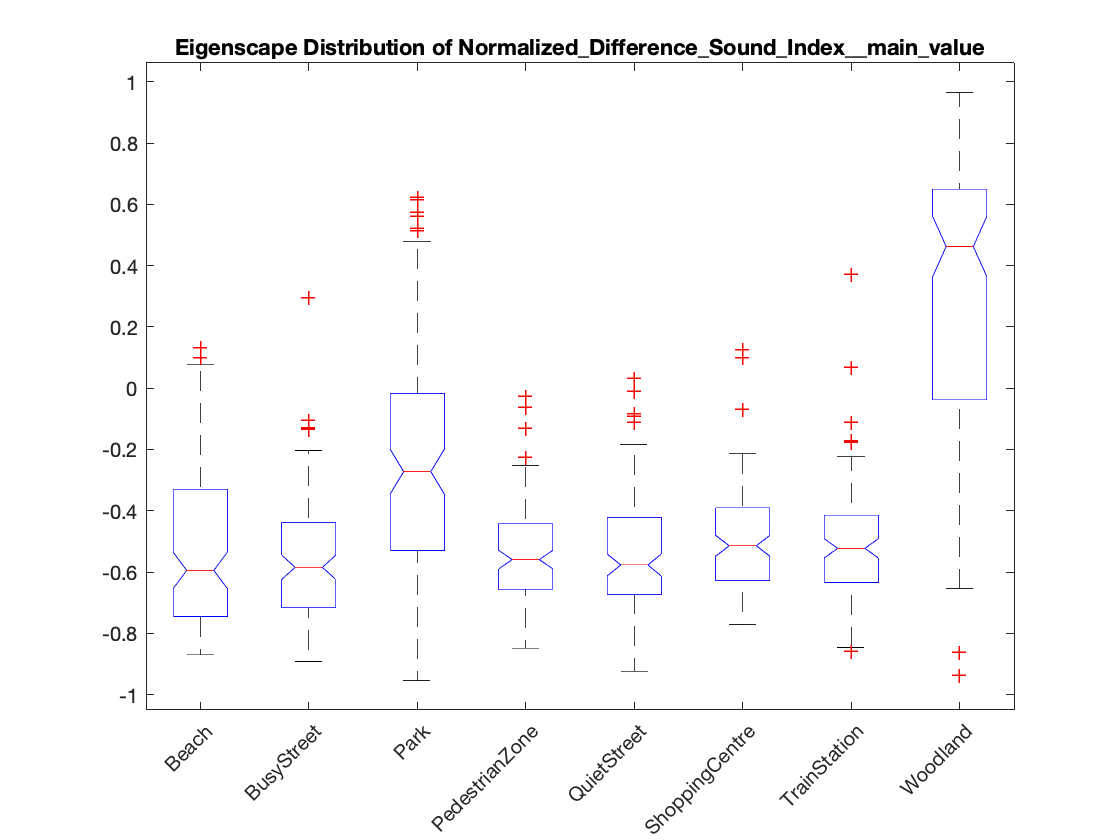

boxplotIndex(highNDSI(:,[1 12]));

The boxplot above would suggest that the two presumably more 'natural' soundscape locations, the woodland and then park, have a much wider NDSI distribution than the other 6 classes who all appeart to have negative NDSI scores. It might be intuitive that the train station, busy street and quiet street classes have large negative NDSI values, and that the range of those scores is predominantly low; the shopping centre might be a surprise, as typical human sounds achieve a negative NDSI score despite being of 'natural origin'. The beach class also appears to have a wholy negative or low positive NDSI score, and it might be that the score is penalised by the low-frequency noise of the wind and the sea. The broad range of woodland soundscape NDSI values might be caused by 

### Acoustic Diversity Index

highADI = sortrows(Indices, 9);
head(highADI(:,[1 9]))

ans = 8×2 table
            filename             Acoustic_Diversity_Index__main_value
    _________________________    ____________________________________

    "Beach.2.08.wav"                           0.77388               
    "PedestrianZone.8.01.wav"                  0.94538               
    "PedestrianZone.8.04.wav"                  0.99884               
    "PedestrianZone.3.08.wav"                   1.0139               
    "BusyStreet.4.08.wav"                       1.0549               
    "PedestrianZone.3.06.wav"                   1.0685               
    "PedestrianZone.3.01.wav"                   1.1189               
    "Park.2.13.wav"                             1.1245               


tail(highADI(:,[1 9]))

ans = 8×2 table
         filename          Acoustic_Diversity_Index__main_value
    ___________________    ____________________________________

    "Woodland.5.10.wav"                   2.3007               
    "Woodland.6.07.wav"                   2.3008               
    "Woodland.5.09.wav"                   2.3008               
    "Woodland.6.10.wav"                    2.301               
    "Woodland.6.12.wav"                    2.301               
    "Woodland.5.03.wav"                    2.301               
    "Woodland.5.06.wav"                    2.301               
    "Woodland.5.04.wav"                   2.3011               


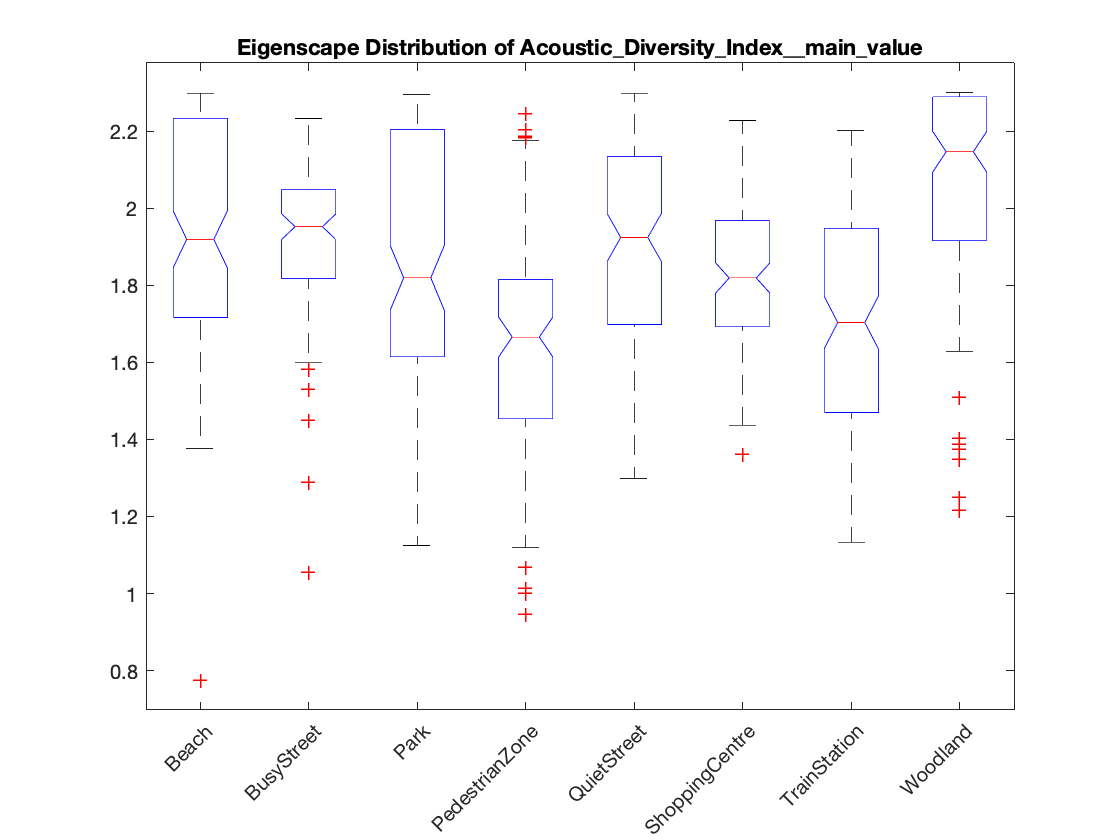

boxplotIndex(highADI(:,[1 9]));

### Acoustic Entropy

totalEntropy = Indices(:,"Spectral_Entropy__main_value").Variables .* Indices(:,"Temporal_Entropy__main_value").Variables;
Indices.Total_Entropy = totalEntropy;
highAE = sortrows(Indices, 21);
head(highAE(:,[1 21]))

ans = 8×2 table
            filename             Total_Entropy
    _________________________    _____________

    "BusyStreet.4.08.wav"           0.61001   
    "PedestrianZone.3.08.wav"       0.61754   
    "PedestrianZone.3.01.wav"       0.61817   
    "Beach.2.08.wav"                0.62542   
    "TrainStation.6.02.wav"           0.627   
    "Beach.3.03.wav"                 0.6293   
    "ShoppingCentre.3.07.wav"        0.6298   
    "Beach.3.10.wav"                0.63039   


tail(highAE(:,[1 21]))

ans = 8×2 table
         filename          Total_Entropy
    ___________________    _____________

    "Woodland.5.08.wav"        0.9576   
    "Woodland.5.04.wav"       0.95936   
    "Woodland.6.07.wav"       0.96167   
    "Woodland.5.01.wav"       0.96235   
    "Woodland.5.03.wav"       0.96237   
    "Woodland.5.14.wav"       0.96684   
    "Woodland.5.12.wav"       0.96715   
    "Woodland.5.13.wav"       0.96857   


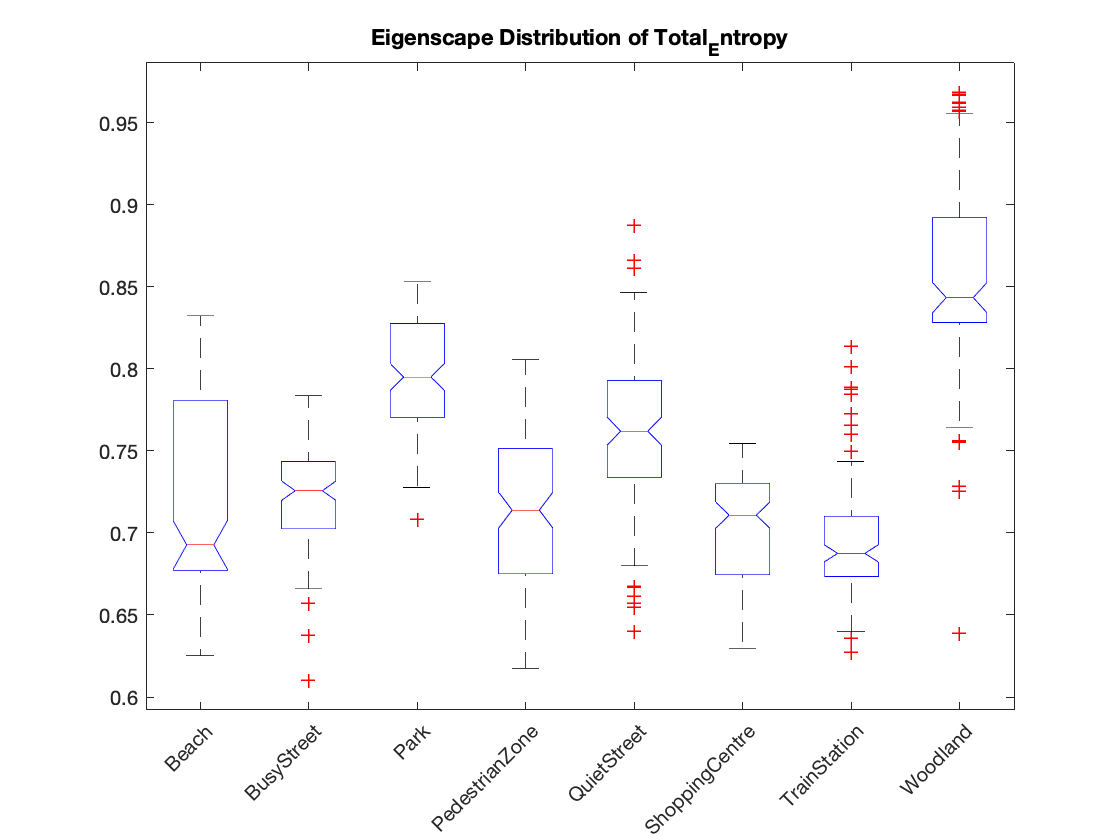

boxplotIndex(highAE(:,[1 21]));

### Sound Clip Exploration

Unsurprisingly 

### References

### Functions

function boxplotIndex(table)
% highNDSI(:,[1 12]);
types = ["Beach" "BusyStreet" "Park" "PedestrianZone" "QuietStreet" "ShoppingCentre" "TrainStation" "Woodland"];
fileNames = table(:,1).Variables;
index = table(:,2).Variables;
for index = 1 : length(types)
    data(:, index) = table(contains(table(:,1).Variables, types(index)) == true, 2).Variables';
end
boxplot(data,'Notch','on','Labels', types,'Whisker',1);
title("Eigenscape Distribution of " + string(table.Properties.VariableNames(2)));
xtickangle(45);
end